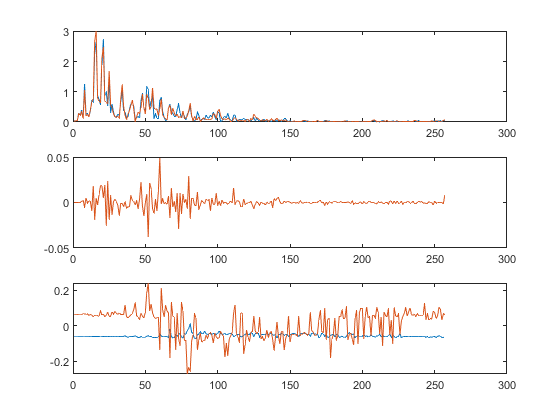

time_frame_now = 10;
% noisy signal f*time*mic 
figure; subplot(3,1,1)
plot(abs(squeeze(y_STFT(:,time_frame_now,:))))
% enhanced signal f*time*mic 
subplot(3,1,2)
plot(real(squeeze(S_mvdr_mwfL_stft(:,time_frame_now,:))))
% weight gain mic*f*time 
subplot(3,1,3)
plot(real(squeeze(weight(1,:,time_frame_now)))); hold on; plot(real(squeeze(weight(2,:,time_frame_now))))

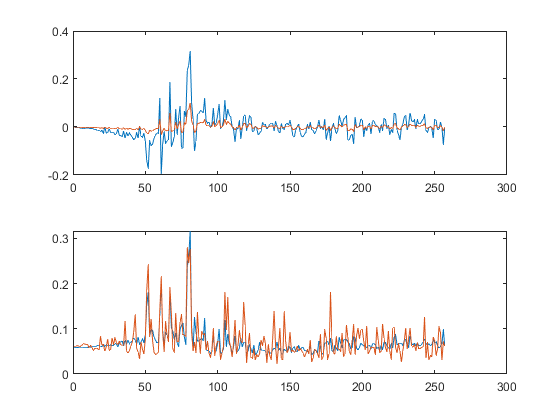

figure ; subplot(2,1,1)
plot(imag(squeeze(weight(1,:,time_frame_now)))); hold on; plot(imag(squeeze(weight(2,:,time_frame_now))));
hold off;
subplot(2,1,2)
plot(abs(squeeze(weight(1,:,time_frame_now)))); hold on; plot(abs((squeeze(weight(2,:,time_frame_now)))));
hold off

aa=weight - weight_com;
ee = mvdr_n1 - mvdr_n2;
sum_ee = sum(sum(ee))

sum_ee = 0.0068 + 0.0000i

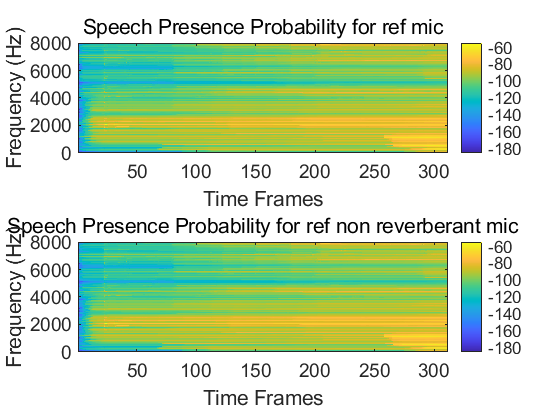

figure; subplot(2,1,1);
imagesc(1:N_frames, f,mag2db(abs(mvdr_n1))); colorbar; axis xy; set(gcf,'color','w');
set(gca,'Fontsize',14), xlabel('Time Frames'), ylabel('Frequency (Hz)'), title('Speech Presence Probability for ref mic');
subplot(2,1,2);
imagesc(1:N_frames, f,mag2db(abs(mvdr_n2))); colorbar; axis xy; set(gcf,'color','w');
set(gca,'Fontsize',14), xlabel('Time Frames'), ylabel('Frequency (Hz)'), title('Speech Presence Probability for ref non reverberant mic');

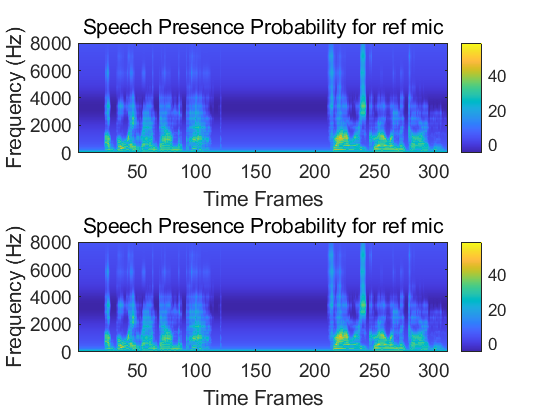

sig = sqrt((10.^((TX_Mask -90)./10)./2)*nfft^2);


tt = psd2spl(sig,nfft);
figure; subplot(2,1,1);
imagesc(1:N_frames, f,tt); colorbar; axis xy; set(gcf,'color','w');
set(gca,'Fontsize',14), xlabel('Time Frames'), ylabel('Frequency (Hz)'), title('Speech Presence Probability for ref mic');

subplot(2,1,2);
imagesc(1:N_frames, f,TX_Mask); colorbar; axis xy; set(gcf,'color','w');
set(gca,'Fontsize',14), xlabel('Time Frames'), ylabel('Frequency (Hz)'), title('Speech Presence Probability for ref mic');

sum_ee = sum(sum(tt-TX_Mask))

sum_ee = NaN

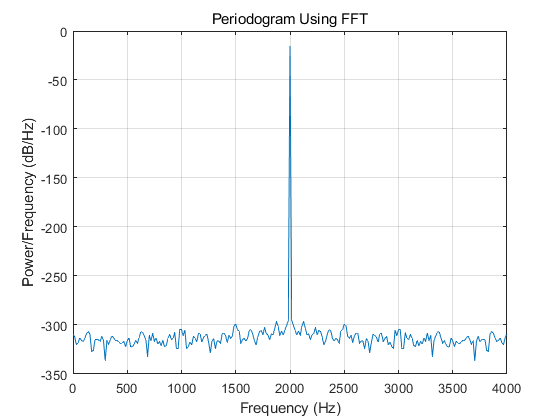

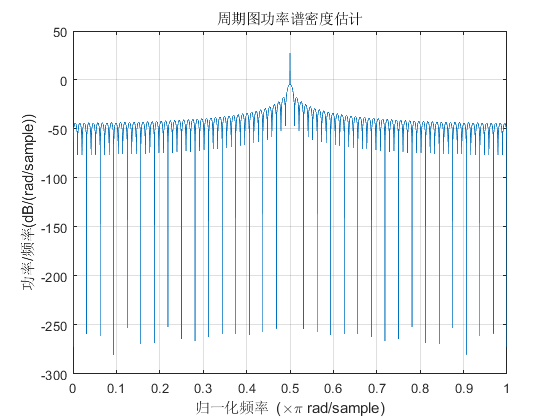

figure
rng default
Fs = 8000;
t = 0:1/Fs:1-1/Fs;
x = cos(2*pi*2000*t) ;
N = 512;
xdft = fft(x,N);
xdft = xdft(1:N/2+1);
psdx = (1/(N*Fs)) * abs(xdft).^2;
psdx(2:end-1) = 2*psdx(2:end-1);
freq = 0:Fs/N:Fs/2;

plot(freq,10*log10(psdx))
grid on
title('Periodogram Using FFT')
xlabel('Frequency (Hz)')
ylabel('Power/Frequency (dB/Hz)')

source_filename{1} = 'speech1.wav';
siglength = 5; 
num_mics = 2;
[aa, bb] = audioread(source_filename{1},'native');

% signal  = resample(source_signals_raw{1},fs_RIR,source_signals_raw{2});

% SPL = splMeter
% SPL = splMeter(Name,Value)
% % b = hz2bark([20,8000]);
%        barkVect = linspace(b(1),b(2),32);
%        hzVect = bark2hz(barkVect);
%        plot(barkVect,hzVect,'o')
%        title('Bark vs Hz')
%        xlabel('Bark')
%        ylabel('Hz')
%        grid on

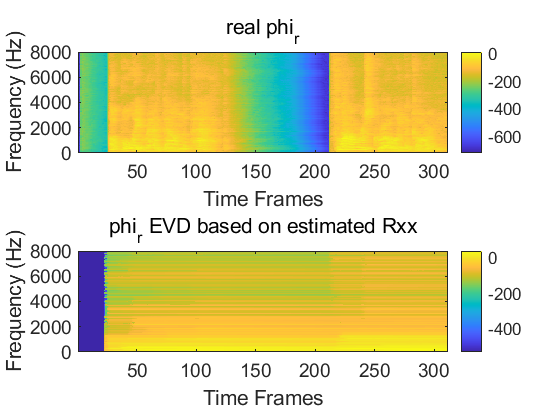

figure; subplot(2,1,1);
imagesc(1:N_frames, f,mag2db(abs(rho_r))); colorbar; axis xy; set(gcf,'color','w');
set(gca,'Fontsize',14), xlabel('Time Frames'), ylabel('Frequency (Hz)'), title('real phi_r');
subplot(2,1,2);
imagesc(1:N_frames, f,mag2db(abs(rho_rev))); colorbar; axis xy; set(gcf,'color','w');
set(gca,'Fontsize',14), xlabel('Time Frames'), ylabel('Frequency (Hz)'),...
    title('phi_r EVD based on estimated Rxx');

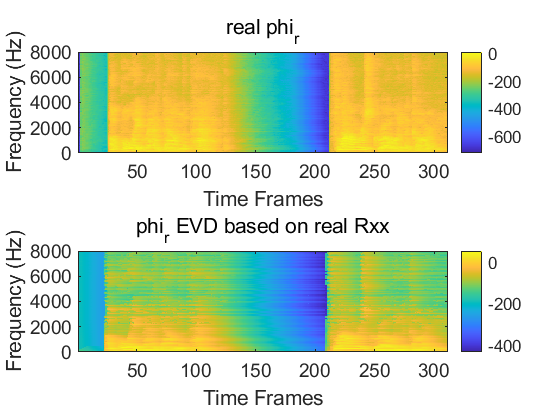

figure; subplot(2,1,1);
imagesc(1:N_frames, f,mag2db(abs(rho_r))); colorbar; axis xy; set(gcf,'color','w');
set(gca,'Fontsize',14), xlabel('Time Frames'), ylabel('Frequency (Hz)'), title('real phi_r');
subplot(2,1,2);
imagesc(1:N_frames, f,mag2db(abs(rho_rev_realx))); colorbar; axis xy; set(gcf,'color','w');
set(gca,'Fontsize',14), xlabel('Time Frames'), ylabel('Frequency (Hz)'),...
    title('phi_r EVD based on real Rxx');

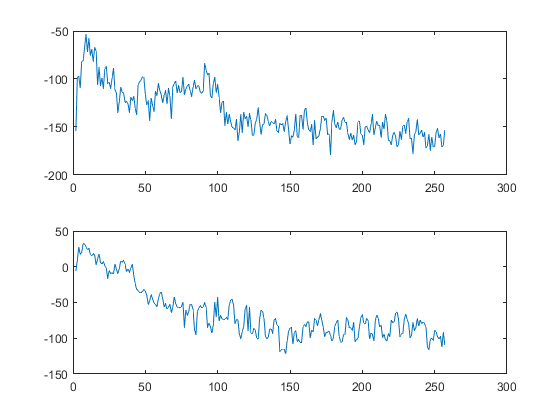

figure; subplot(2,1,1)
plot(mag2db(abs(rho_r(:,311))));
subplot(2,1,2)
plot(mag2db(abs(rho_rev(:,311))));

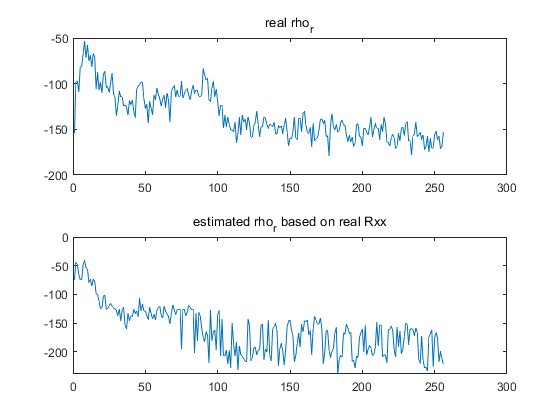

figure; subplot(2,1,1)
plot(mag2db(abs(rho_r(2:257,311)))); title('real rho_r')
subplot(2,1,2)
plot(mag2db(abs(rho_rev_realx(2:257,311))));title('estimated rho_r based on real Rxx')

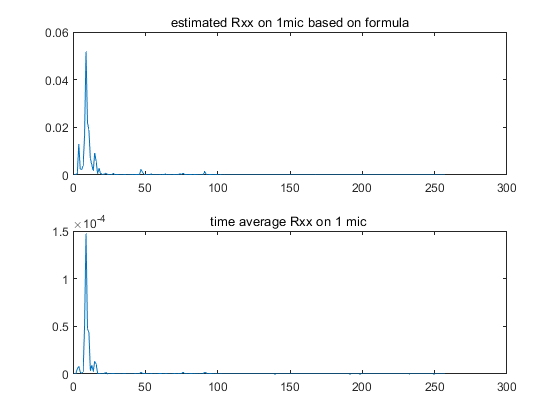

Rxx_esti = cell(N_freqs,1);
for k = 2:257
Rxx_esti{k} = rho_s(k,311) * h_steer(:,k)*h_steer(:,k)'+ rho_r(k,311)*gama{k};
Rxx1_esti(k,1) = Rxx_esti{k}(1,1);
aa(k,1) = rho_s(k,311)+rho_r(k,311);
Rxx1(k,1) = Rxx{k}(1,1);
end
Rxx;
figure; subplot(2,1,1);
plot(abs(aa*20)); title('estimated Rxx on 1mic based on formula');
subplot(2,1,2);
plot(abs(Rxx1));title('time average Rxx on 1 mic ');

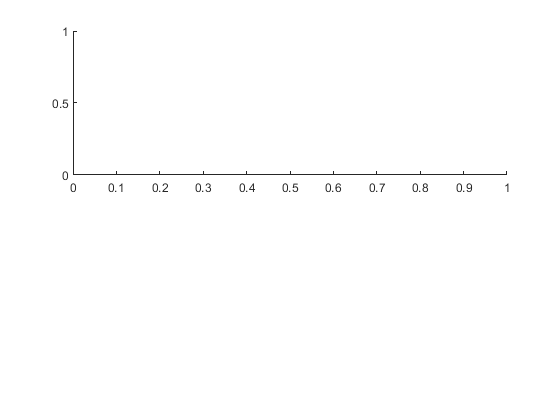

figure; subplot(2,1,1);

imagesc(1:N_frames, f,mag2db(abs(x_STFT(:,:,1)))); colorbar; axis xy; set(gcf,'color','w');

错误使用 image
颜色数据必须为 m×n×3 或 m×n 矩阵。

出错 imagesc (line 52)
    hh = image(varargin{:}, 'CDataMapping', 'scaled');

set(gca,'Fontsize',14), xlabel('Time Frames'), ylabel('Frequency (Hz)'), title('real phi_r');
subplot(2,1,2);
imagesc(1:N_frames, f,mag2db(abs(xe_STFT(:,:,)))); colorbar; axis xy; set(gcf,'color','w');
set(gca,'Fontsize',14), xlabel('Time Frames'), ylabel('Frequency (Hz)'),...
    title('phi_r EVD based on real Rxx');